
clc, clear all
%% MNIST datapath
train_images_file = 'data/train-images.idx3-ubyte';
train_labels_file = 'data/train-labels.idx1-ubyte';
test_images_file  = 'data/t10k-images.idx3-ubyte';
test_labels_file  = 'data/t10k-labels.idx1-ubyte';


%% Load data
train_data = loadMNISTImages(train_images_file);
train_labels = loadMNISTLabels(train_labels_file);
test_data = loadMNISTImages(test_images_file);
test_labels = loadMNISTLabels(test_labels_file);

% Display dataset relevant information
fprintf('Train data length: %d images\n', length(train_data));

Train data length: 60000 images


fprintf('Train labels length: %d labels\n', length(train_labels));

Train labels length: 60000 labels


fprintf('Test data length: %d images\n', length(test_data));

Test data length: 10000 images


fprintf('Test labels length: %d labels\n', length(test_labels));

Test labels length: 10000 labels


fprintf('Train data shape: [%d %d %d]\n', size(train_data));

Train data shape: [784 60000 

fprintf('Test data shape: [%d %d %d]\n', size(test_data));

Test data shape: [784 10000 

fprintf('First label: %d\n', train_labels(1));

First label: 5


fprintf('Pixel value range: %d to %d\n', min(train_data(:)), max(train_data(:)));

Pixel value range: 0 to 1


fprintf('Unique labels: %s\n', mat2str(unique(train_labels)));

Unique labels: [0;1;2;3;4;5;6;7;8;9]



%% Reshape input and test data to 28x28
train_data = reshape(train_data, 28, 28, []);
test_data = reshape(train_data, 28, 28, []);

% Display new data shape
fprintf('Train data shape: [%d %d %d]\n', size(train_data));

Train data shape: [28 28 60000]


fprintf('Test data shape: [%d %d %d]\n', size(test_data));

Test data shape: [28 28 60000]


fprintf('Pixel value range: %d to %d\n', min(train_data(:)), max(train_data(:)));

Pixel value range: 0 to 1


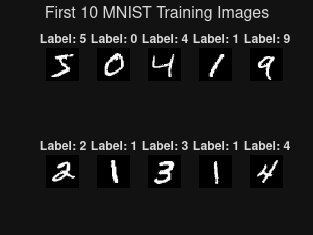


%% Display 10 MNIST examples
figure;
for i = 1:10
    subplot(2,5,i);
    imshow(train_data(:,:,i), []);
    title(sprintf('Label: %d', train_labels(i)));
end
sgtitle('First 10 MNIST Training Images');